## 问题1

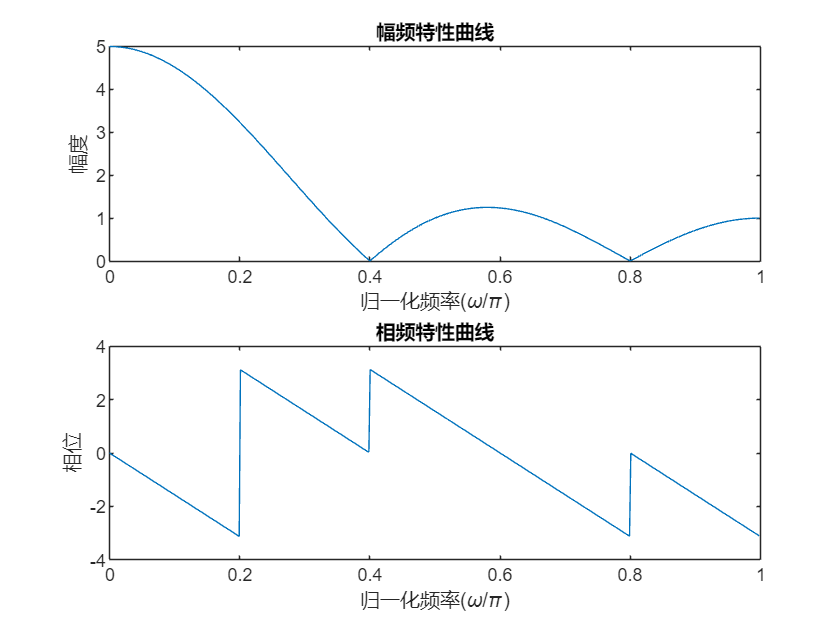

% 定义序列x(n)
n = -5:5;
x = rectpuls(n, 5); % Rs(n)可以用矩形脉冲函数rectpuls来近似表示，宽度为5

% 计算DTFT
[X,w] = freqz(x,1);

% 计算幅频特性
magX = abs(X);

% 计算相频特性
phaseX = angle(X);

% 绘制幅频曲线
subplot(2,1,1);
plot(w/pi, magX);
title('幅频特性曲线');
xlabel('归一化频率(\omega/\pi)');
ylabel('幅度');

% 绘制相频曲线
subplot(2,1,2);
plot(w/pi, phaseX);
title('相频特性曲线');
xlabel('归一化频率(\omega/\pi)');
ylabel('相位');

## 问题2

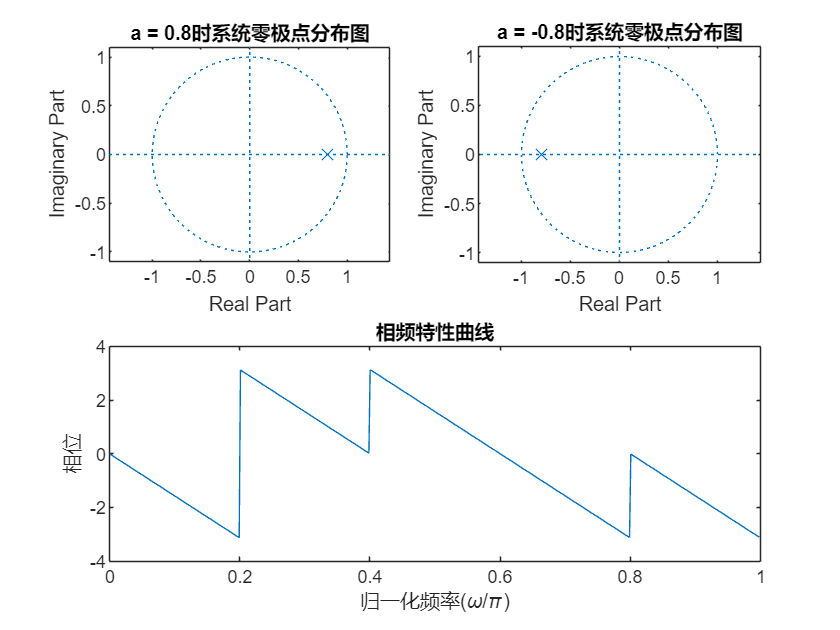

% 定义参数
a1 = 0.8;
a2 = -0.8;

% 计算零极点
z1 = [];
p1 = [a1];
z2 = [];
p2 = [a2];

% 绘制零极点分布图（a = 0.8）
subplot(2,2,1);
zplane(z1,p1);
title('a = 0.8时系统零极点分布图');

% 绘制零极点分布图（a = -0.8）
subplot(2,2,2);
zplane(z2,p2);
title('a = -0.8时系统零极点分布图');

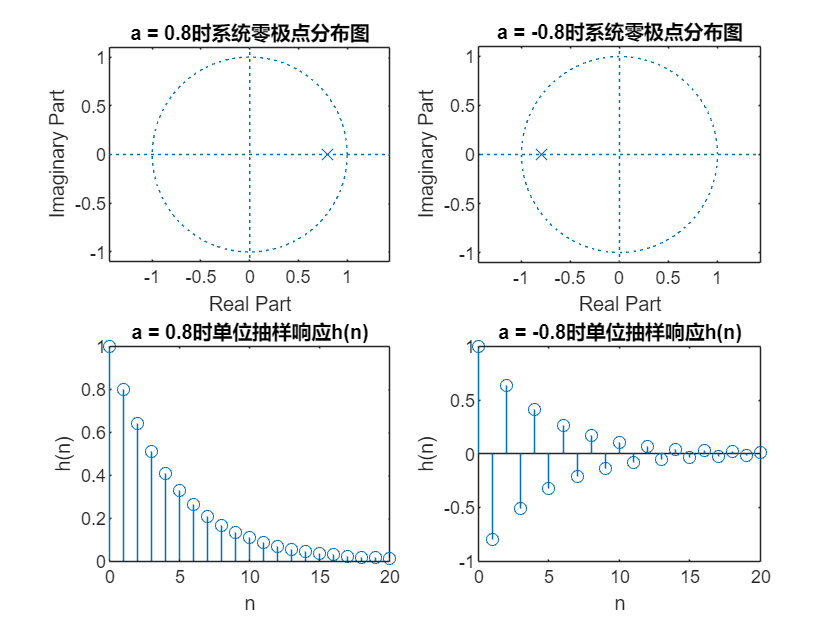


% 计算单位抽样响应h(n) （a = 0.8）
n1 = 0:20;
impulse_signal1 = [1, zeros(1, length(n1)-1)];  % 手动生成单位脉冲信号
h1 = filter(1, [1 -a1], impulse_signal1); % 计算单位抽样响应
% 绘制单位抽样响应（a = 0.8）
subplot(2,2,3);
stem(n1,h1);
title('a = 0.8时单位抽样响应h(n)');
xlabel('n');
ylabel('h(n)');

% 计算单位抽样响应h(n) （a = -0.8）
n2 = 0:20;
impulse_signal2 = [1, zeros(1, length(n2)-1)];  % 手动生成单位脉冲信号
h2 = filter(1, [1 -a2], impulse_signal2); % 计算单位抽样响应
% 绘制单位抽样响应（a = -0.8）
subplot(2,2,4);
stem(n2,h2);
title('a = -0.8时单位抽样响应h(n)');
xlabel('n');
ylabel('h(n)');

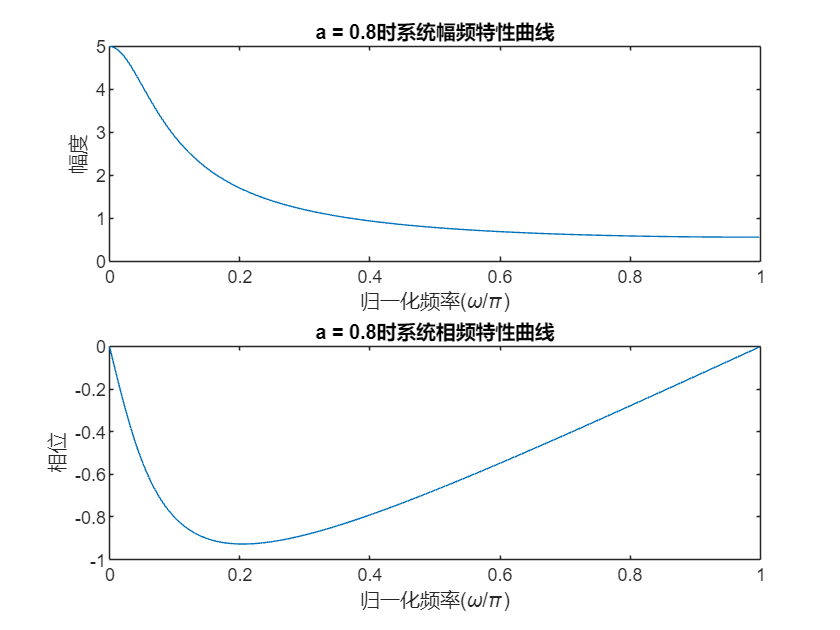


% 计算频率响应并绘制幅频和相频曲线（a = 0.8）
[H1, w1] = freqz(1, [1 -a1]);
magH1 = abs(H1);
phaseH1 = angle(H1);
figure;
subplot(2,1,1);
plot(w1/pi, magH1);
title('a = 0.8时系统幅频特性曲线');
xlabel('归一化频率(\omega/\pi)');
ylabel('幅度');
subplot(2,1,2);
plot(w1/pi, phaseH1);
title('a = 0.8时系统相频特性曲线');
xlabel('归一化频率(\omega/\pi)');
ylabel('相位');

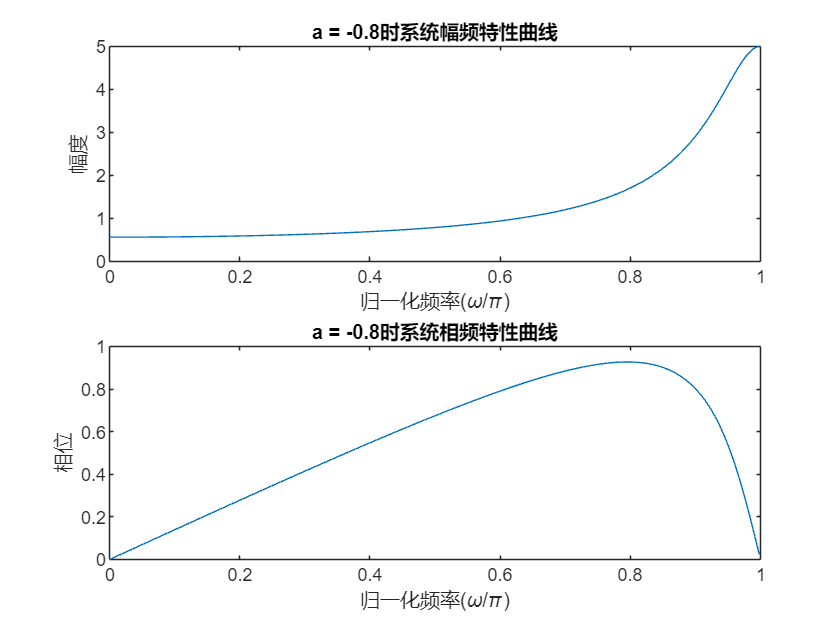


% 计算频率响应并绘制幅频和相频曲线（a = -0.8）
[H2, w2] = freqz(1, [1 -a2]);
magH2 = abs(H2);
phaseH2 = angle(H2);
figure;
subplot(2,1,1);
plot(w2/pi, magH2);
title('a = -0.8时系统幅频特性曲线');
xlabel('归一化频率(\omega/\pi)');
ylabel('幅度');
subplot(2,1,2);
plot(w2/pi, phaseH2);
title('a = -0.8时系统相频特性曲线');
xlabel('归一化频率(\omega/\pi)');
ylabel('相位');